# **Problems Week 6**

**Answer: **[**https://docs.google.com/document/d/1dfJIGcQQOklqILjjZAf4fVUmqdee6zdXPwGhkiblwNg/edit**](https://docs.google.com/document/d/1dfJIGcQQOklqILjjZAf4fVUmqdee6zdXPwGhkiblwNg/edit)

## **P6-1**

Use the **eye** function to create a 4 x 5 diagonal matrix called ***A*** with 7’s on the leading diagonal.

% Create a 4x5 diagonal matrix A with 7s on the leading diagonal
A = 7 * eye(4, 5);
disp('A = ');

A = 


disp(A);

     7     0     0     0     0
     0     7     0     0     0
     0     0     7     0     0
     0     0     0     7     0



## **P6-2**

Create a 3 x 3 elementary matrix called ***E*** that adds 3 of the 1st row to the 3rd row of a matrix. Test it with a random 3 x 3 matrix of integers.

% Define the elementary matrix E
E = eye(3);  % Create a 3x3 identity matrix
E(3, 1) = 3; % Set the element in the 3rd row and 1st column to 3

% Create a random 3x3 matrix of integers
A = randi([-10, 10], 3, 3);

% Apply the elementary matrix E to A
B = E * A;

% Display the original matrix A and the result matrix B
disp('Original Matrix:');

Original Matrix:


disp(A);

   -10    -7    -9
    -2    -7     2
    -4    -2    -1



disp('After Row Operation:');

After Row Operation:


disp(B);

   -10    -7    -9
    -2    -7     2
   -34   -23   -28



## **P6-3**

Augment the test matrix from question 2 with a 3 x 3 identity matrix then use Matlab’s **rref** function to find it’s reduced echelon form.

% Augment A with a 3x3 identity matrix
B = [A, eye(3)];

% Find the reduced row echelon form (RREF) using rref
RREF_B = rref(B);

% Display the augmented matrix B and its RREF
disp('Augmented Matrix:');

Augmented Matrix:


disp(B);

   -10    -7    -9     1     0     0
    -2    -7     2     0     1     0
    -4    -2    -1     0     0     1



disp('RREF:');

RREF:


disp(RREF_B);

    1.0000         0         0    0.0625    0.0625   -0.4375
         0    1.0000         0   -0.0568   -0.1477    0.2159
         0         0    1.0000   -0.1364    0.0455    0.3182



## **P6-4**

Create the coefficient matrix for the following linear system, check that its determinant is not 0, then calculate the solution using the inverse matrix method (hint: you can find the inverse of a matrix with the inv function).

## 
$$3x_1 +4x_2 =3$$


## 
$$5x_1 +6x_2 =7$$


## 
$$x=A^{-1} b$$


% Coefficient matrix A
A = [3 4; 5 6];

% Constant vector b
b = [3; 7];

% Step 1: Check if the determinant of A is nonzero
detA = det(A);

if detA == 0
    disp("The determinant of A is zero. The system may not have a unique solution.");
else
    % Step 2: Calculate the inverse of A
    A_inv = inv(A);
    
    % Step 3: Solve for x using the inverse matrix method
    x = A_inv * b;
    
    % Display the solution
    disp("The solution is:");
    for i = 1:length(x)
        fprintf("x%d = %.2f\n", i, x(i));
    end
end

The solution is:


x1 = 5.00
x2 = -3.00


## **P6-5**

Solve the system above but using Matlab’s left-division operator.

% Coefficient matrix A
A = [3 4; 5 6];

% Constant vector b
b = [3; 7];

% Solve for x using the left-division operator
x = A \ b;

% Display the solution
disp("The solution is:");

The solution is:


fprintf("x1 = %.2f\n", x(1));

x1 = 5.00


fprintf("x2 = %.2f\n", x(2));

x2 = -3.00


## **P6-6**

There are 3 reactors linked by pipes as shown below. The rate of transfer of chemicals through each pipe is equal to a flow rate (Q, with units of cubic meters per ­second) multiplied by the concentration of the reactor from which the flow originates (c, with units of milligrams per cubic meter). If the system is at a steady state, the transfer into each reactor will balance the transfer out. Develop mass-balance equations for the reactors and solve the three simultaneous linear algebraic equations for their concentrations.

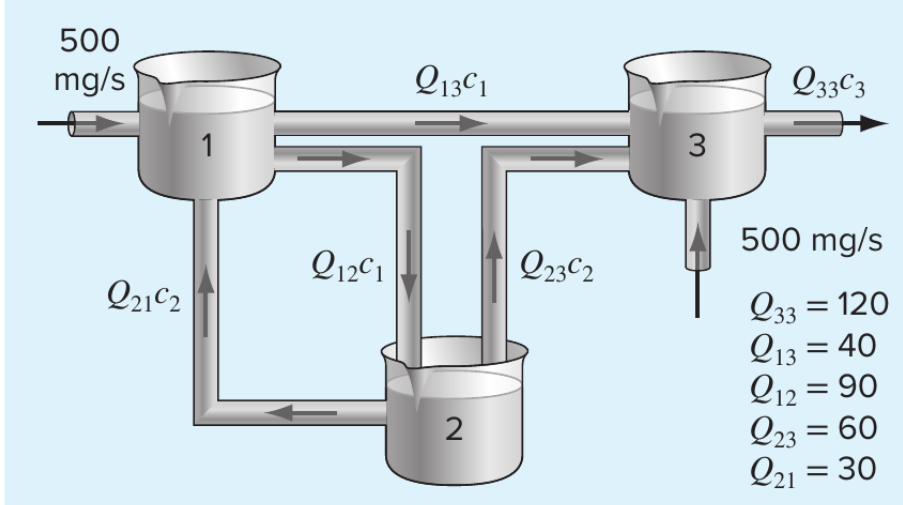

% Given flow rates
Q33 = 120;
Q13 = 40;
Q12 = 90;
Q23 = 60;
Q21 = 30;

% Coefficients of the equations
A = [-Q13-Q12, Q21, -Q23; Q12, -Q21-Q23, 0; Q13, Q23, -Q33];
B = [-500; 0; 500];

% Solve the system of equations
C = A \ B;

% Extract concentrations
C1 = C(1);
C2 = C(2);
C3 = C(3);

% Display the results
fprintf('The value of C1 is %.4f mg/m^3\n', C1);

The value of C1 is 5.0000 mg/m^3


fprintf('The value of C2 is %.4f mg/m^3\n', C2);

The value of C2 is 5.0000 mg/m^3


fprintf('The value of C3 is %.4f mg/m^3\n', C3);

The value of C3 is -0.0000 mg/m^3


## **P6-7**

Use Matlab’s **fsolve** function to find the roots of the system. Since there are infinite solutions you do not need to find every root. Just locate and plot those given in the default window. Plotting is always a good idea to give you an idea of how many roots you are looking for and where to make the initial guesses. Use the **fimplicit** function to plot these implicit functions on the same graph. Define a function at the end of your script closed with keyword **end** that holds the system of equations. Advanced users can also use the ginput() function to pick starting initial guesses.

## 
$$e^{\mathrm{xy}} -y^2 =0$$


## 
$$\cos \left(x+y\right)=0$$


% Define the system of equations
% Use fsolve to find the roots
initialGuesses = [0.5, 5; 0.5, 0.5; -0.5, 0.5; -0.5, -5; -0.5, -0.5; 2, -0.5];
roots = [];

for i = 1:size(initialGuesses, 1)
    root = fsolve(@equations, initialGuesses(i, :));
    roots = [roots; root];
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

% Display the roots
disp('The roots are:');

The roots are:


disp(roots);

    0.6922    4.0202
    0.3387    1.2320
   -2.1254    0.5546
   -0.6922   -4.0202
   -0.3387   -1.2320
    2.1254   -0.5546



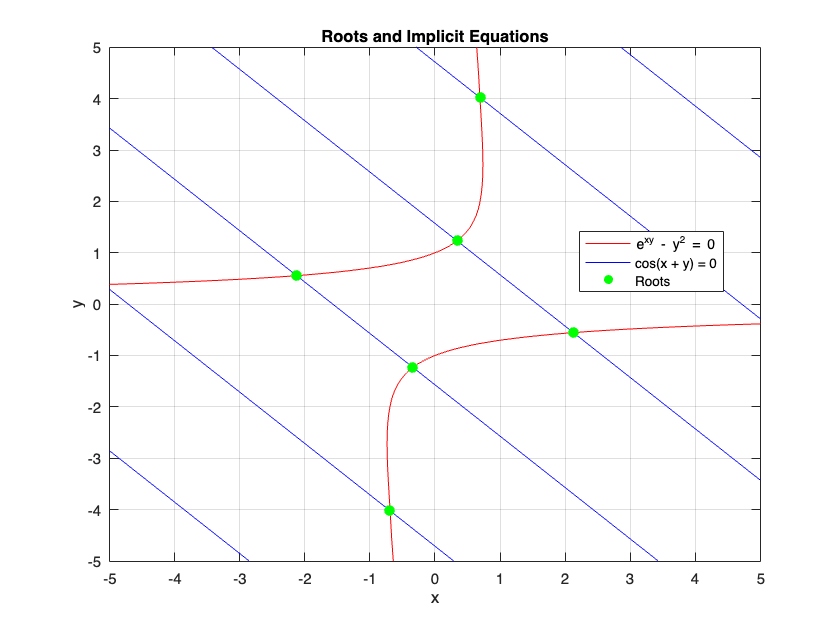

% Plotting using fimplicit
figure;

% Define the implicit functions using function handles
f1 = @(x, y) exp(x .* y) - y.^2;
f2 = @(x, y) cos(x + y);

% Plot the implicit functions
fimplicit(f1, [-5 5 -5 5], 'r');
hold on;
fimplicit(f2, [-5 5 -5 5], 'b');
scatter(roots(:, 1), roots(:, 2), 50, 'go', 'filled');
title('Roots and Implicit Equations');
xlabel('x');
ylabel('y');
legend('e^{xy} - y^2 = 0', 'cos(x + y) = 0', 'Roots', 'Location', 'best');
grid on;
hold off;

## **P6-8**

Find a root of the following system. Check your solution.

## 
$$3x-\cos \left(\;\mathrm{yz}\right)=\frac{3}{2}$$


## 
$$4x^2 -625y^2 +2z=1$$


## 
$$20z+e^{-\mathrm{xy}} =-9$$


% Use fsolve to find a root
initialGuess = [0, 0, 0];
[x_sol, fval, exitflag] = fsolve(@myEquations, initialGuess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


%x_sol is the output variable where the solution to the system of equations is stored. x_sol contains the values of x, y, and z.
%fval is the output variable that contains the values of the equations evaluated at the solution x_sol.
%exitflag is the output variable that indicates the exit condition of the solver. 
% A positive exitflag typically indicates a successful convergence to a solution, while a negative value may indicate issues or failure to find a solution.

x = x_sol(1);
y = x_sol(2);
z = x_sol(3);

% Check the solution
if exitflag > 0
    fprintf('Root found:\n');
    fprintf('x = %.6f\n', x);
    fprintf('y = %.6f\n', y);
    fprintf('z = %.6f\n', z);
else
    fprintf('No root found or an error occurred.\n');
end

Root found:


x = 0.833281


y = -0.035201


z = -0.501488


% Evaluate the equations with the solution
eq1 = 3 * x - cos(y * z) - 3/2;
eq2 = 4 * x^2 - 625 * y^2 + 2 * z - 1;
eq3 = 20 * z + exp(-x * y) + 9;

fprintf('Substituting into the first equation gives: %e\n', eq1);

Substituting into the first equation gives: 0.000000e+00


fprintf('Substituting into the second equation gives: %e\n', eq2);

Substituting into the second equation gives: -1.358913e-13


fprintf('Substituting into the third equation gives: %e\n', eq3);

Substituting into the third equation gives: 0.000000e+00


## **P6-9**

Write a script that uses the Newton Method for Nonlinear Systems to solve the following nonlinear system. Try to find the roots of the system with your script. Remember you’ll have to compute the Jacobian yourself by hand for now in order to put it into your script. 3x^2+2y^2=25 2x^2-y=15

## 
$$3x^2 +2y^2 =25$$


## 
$$2x^2 -y=15$$


% Define the symbolic variables
syms x y;

% Define the equations
eq1 = 3*x^2 + 2*y^2 - 25;
eq2 = 2*x^2 - y - 15;

% Create the vector-valued function F
F = [eq1; eq2];

% Initialize the roots array
roots = [];

% Iterate over different initial guesses
initial_guesses = [1, 1; -1, 1; -1, -1; 1, -1];
for i = 1:size(initial_guesses, 1)
    x0 = initial_guesses(i, :)';
    
    % Tolerance for convergence
    tolerance = 1e-6;

    % Maximum number of iterations
    maxIterations = 100;

    % Initialize the Jacobian matrix
    Jacobian = jacobian(F, [x, y]);

    % Start the Newton-Raphson iteration
    for iter = 1:maxIterations
        % Calculate the value of F and Jacobian at the current point
        F_value = double(subs(F, [x; y], x0));
        J_value = double(subs(Jacobian, [x; y], x0));

        % Solve the linear system to get the update
        delta = -J_value \ F_value;

        % Update the current point
        x0 = x0 + delta;

        % Check for convergence
        if norm(delta) < tolerance
            roots = [roots; x0'];
            break;
        end
    end
end
% Display the roots
fprintf('The roots are:\n');

The roots are:


disp(roots);

    2.8111    0.8042
   -2.8111    0.8042
   -2.5929   -1.5542
    2.5929   -1.5542



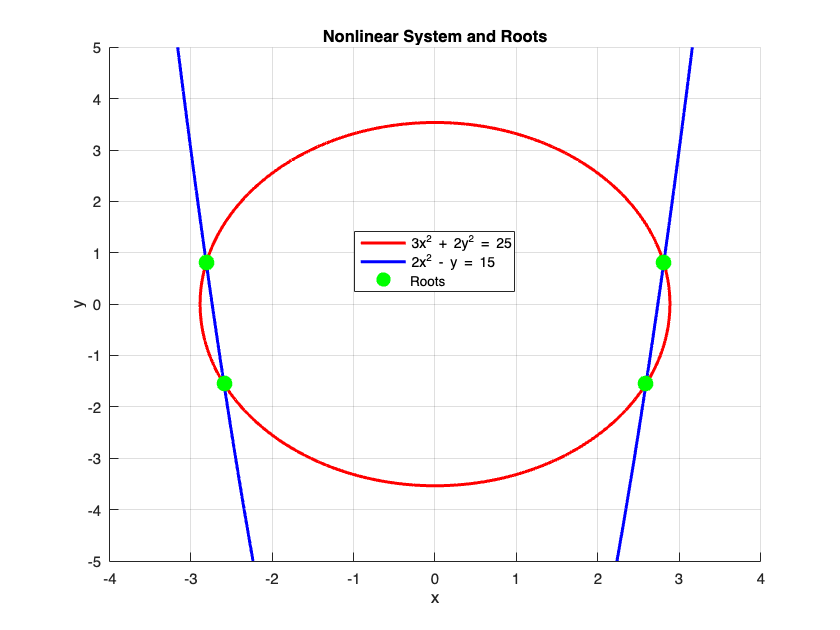

% Create a plot
figure;
hold on;

% Plot the equations
fimplicit(eq1, 'r', 'LineWidth', 2);
fimplicit(eq2, 'b', 'LineWidth', 2);

% Plot the roots
plot(roots(:, 1), roots(:, 2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');

xlabel('x');
ylabel('y');
title('Nonlinear System and Roots');
legend('3x^2 + 2y^2 = 25', '2x^2 - y = 15', 'Roots', 'Location', 'Best');
grid on;

hold off;

## **P6-10**

Write a script that reduces a 3 x 3 matrix to an echelon form (don’t worry about pivoting). Test it on the following matrix:

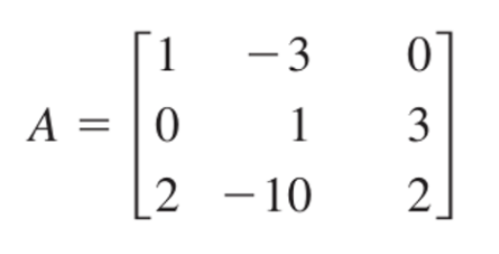

% Define the input matrix A
A = [1, -3, 0; 0, 1, 3; 2, -10, 2];

% Display the original matrix A
fprintf('Original Matrix A:\n');

Original Matrix A:


disp(A);

     1    -3     0
     0     1     3
     2   -10     2



% Subtract row 1 multiplied by 2 from row 3: R3 = R3 - 2 * R1
A(3, :) = A(3, :) - 2 * A(1, :);

% Display the matrix after the first row operation
fprintf('After R3 = R3 - 2 * R1:\n');

After R3 = R3 - 2 * R1:


disp(A);

     1    -3     0
     0     1     3
     0    -4     2



% Add row 2 multiplied by 3 to row 1: R1 = R1 + 3 * R2
A(1, :) = A(1, :) + 3 * A(2, :);

% Display the matrix after the second row operation
fprintf('After R1 = R1 + 3 * R2:\n');

After R1 = R1 + 3 * R2:


disp(A);

     1     0     9
     0     1     3
     0    -4     2



% Add row 2 multiplied by 4 to row 3: R3 = R3 + 4 * R2
A(3, :) = A(3, :) + 4 * A(2, :);

% Display the final echelon form matrix
fprintf('Echelon Form Matrix A:\n');

Echelon Form Matrix A:


disp(A);

     1     0     9
     0     1     3
     0     0    14



## **P6-11**

Write a script that reduces the above matrix to reduced echelon form (RREF).

% Compute the RREF of matrix A
RREF_A = rref(A);

% Display the RREF of matrix A
fprintf('Reduced Row Echelon Form (RREF) of Matrix A:\n');

Reduced Row Echelon Form (RREF) of Matrix A:


disp(RREF_A);

     1     0     0
     0     1     0
     0     0     1



## **P6-12**

Write a script that finds the LU factorisation of the matrix ***A*** in question 10 using Gaussian elimination to find ***U*** and the formulae given in lecture notes 6 to find ***L***.

A = [1, -3, 0; 0, 1, 3; 2, -10, 2];
[n, ~] = size(A);

% Initialize L as an identity matrix
L = eye(n);

% Initialize U as a copy of A
U = A;

% Perform Gaussian elimination to find U and the elements of L
for k = 1:n-1
    for i = k+1:n
        % Calculate the multiplier for the elimination
        L(i, k) = U(i, k) / U(k, k);
        
        % Update the elements of U and L
        U(i, k:n) = U(i, k:n) - L(i, k) * U(k, k:n);
    end
end

% Display the matrices L and U
fprintf('Matrix L:\n');

Matrix L:


disp(L);

     1     0     0
     0     1     0
     2    -4     1



fprintf('Matrix U:\n');

Matrix U:


disp(U);

     1    -3     0
     0     1     3
     0     0    14



## **P6-13**

Solve the above system using LU factorisation but use Matlab’s built in** lu** function. Note you must account for the permutation matrix given by Matlab.

% Define the right-hand side vector
b = [-5; -1; -20];

% Solve Ly = b using forward substitution
n = length(b);
y = zeros(n, 1);

y(1) = b(1) / L(1, 1);
for i = 2:n
    y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
end

% Solve Ux = y using backward substitution
x = zeros(n, 1);

x(n) = y(n) / U(n, n);
for i = n-1:-1:1
    x(i) = (y(i) - U(i, i+1:n) * x(i+1:n)) / U(i, i);
end

% Display the solution
fprintf('Solution:\n');

Solution:


disp(x);

     1
     2
    -1



## **P6-14**

Solve the above system using LU factorisation but use Matlab’s built in** lu** function. Note you must account for the permutation matrix given by Matlab.

A = [10 6 10 4 -7; -7 -8 3 5 4; 10 -2 -10 5 -10; 10 9 7 -2 -5; 0 6 9 3 -10];
disp("Matrix A");

Matrix A


A

A =     10     6    10     4    -7
    -7    -8     3     5     4
    10    -2   -10     5   -10
    10     9     7    -2    -5
     0     6     9     3   -10


A_inverse = calculate_inverse(A);
disp("The invers is A^(-1)");

The invers is A^(-1)


A_inverse

A_inverse =    -0.0637    0.1103    0.0509    0.1900   -0.0572
    0.6069   -0.5884   -0.1946   -0.8241   -0.0535
   -0.2148    0.2518    0.0393    0.3518    0.0359
    0.7049   -0.5136   -0.1601   -0.9043   -0.0866
    0.3822   -0.2805   -0.1295   -0.4491   -0.1257


check = A * A_inverse;
disp("Check A*A_inverse");

Check A*A_inverse


check

check =     1.0000    0.0000   -0.0000         0   -0.0000
   -0.0000    1.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000    1.0000         0
    0.0000   -0.0000   -0.0000   -0.0000    1.0000


function F = equations(x)
    F = [exp(x(1) * x(2)) - x(2)^2;
         cos(x(1) + x(2))];
end

function inverse_matrix = calculate_inverse(matrix)
    % Check if the input matrix is square
    [m, n] = size(matrix);
    if m ~= n
        error('Input matrix must be square.');
    end
    
    % Check if the determinant of the matrix is zero
    if abs(det(matrix)) < eps
        error('Matrix is not invertible (determinant is zero).');
    end
    
    % Calculate the inverse using MATLAB's built-in function
    inverse_matrix = inv(matrix);
end

function F = myEquations(X)
    x = X(1);
    y = X(2);
    z = X(3);

    F(1) = 3 * x - cos(y * z) - 3/2;
    F(2) = 4 * x^2 - 625 * y^2 + 2 * z - 1;
    F(3) = 20 * z + exp(-x * y) + 9;
end
